# Ecuaciones lineales de primer orden  

# Problemas de valor inicial

#### Use separation of variables to find solutions of the IVP given by y(0) = 1 and the following differential equations:

(a)$\frac{\mathrm{d}}{\mathrm{d}t}y=t$    (b) $\frac{\mathrm{d}}{\mathrm{d}t}y=t^2 y$    (c) $\frac{\mathrm{d}}{\mathrm{d}t}y=2\left(t+1\right)y\;$

% t en [0,2]

### Resuelve numéricamente los siguientes problemas.

Compara en una gráfica las soluciones obtenidas por diferentes métodos.


$$y^{\prime } =y\left(1-y\right)$$
      
$$y\left(0\right)=1/2$$


% t en [0,6]


$$y^{\prime } =k{\left(a_0 -y\right)}^2 \left(b_0 -y/2\right)$$
     
$$y\left(0\right)=0$$


$k=0\ldotp 00713$; $a_0 =4$; $b_0 =1$

% t en [0,400]

Resuelve el siguiente problema de valor inicial en el intervalo de $t=0$ a $t=2$


$$y^{\prime } =yt^2 -1\ldotp 1y$$
      
$$y\left(0\right)=1$$


Utilizando los métodos de Euler y RK4, encuentra la solución numérica del problema con valor inicial

$\frac{\mathrm{d}}{\mathrm{d}t}y=3-2t-0\ldotp 5y$  ; $y\left(0\right)=1$

en el intervalo $\textrm{tspan}=\left\lbrack 0,1\right\rbrack$.

Resuelve el problema con el método de Euler y h=0.00001, guarda los resultados en la variable $\textrm{yE}$ y mide el tiempo de ejecución.

h = 0.00001;
tspan = [0 1];
y0 = 1;
f = @(t, y) 3 - 2*t - 0.5*y;

tic
[~, yE] = odeEuler(f, y0, tspan, h);
toc

Resuelve el problema con el método RK4 y h=0.00001, guarda los resultados en la variable $\textrm{yRK4}$ y mide el tiempo de ejecución.

tic
[~, yRK4] = odeRK4(f, y0, tspan, h);
toc

¿Cuál método es más rápido? ¿Por qué?

% Euler, por que la cantidad de evaluaciones en cada instante 
% que hace a la funcion es 1
% en el caso de RK4 son 4 evaluaciones por cada instante

Resuelve nuevamente el problema con ambos métodos pero ahora con h=0.1 y sin medir tiempos.

h = 0.1;
[tE, yE] = odeEuler(f, y0, tspan, h);
[tRK4, yRK4] = odeRK4(f, y0, tspan, h);

La solución exacta del problema es


$$y=14-4t-13\;\exp \left(-\frac{t}{2}\right)$$


Gráfica en una misma figura la solución exacta y los últimos valores calculados de$\textrm{yE}$ y de $\textrm{yRK4}\;$.

y = @(t) 14-4*t-13*exp(-t/2);

fplot(y, tspan)
hold on
plot(tE, yE)
plot(tRK4, yRK4)
legend('Exacta','Euler','RK4','Location','best')
title('Euler vs RK4')
xlabel('$t$','Interpreter','latex')
ylabel('$y$','Interpreter','latex')
hold off

¿Cuál método tiene más error? ¿Por qué?

% Euler, por que solo utiliza una evaluacion de la funcion, por lo que es
% del orden de O(h), mientras que RK4 al utilizar cuatro evaluaciones
% tenemos un error del orden O(h^4)

Use Euler’s method with h = 0.1 to approximate the solution of the IVP

$y^{\prime } =y-\frac{y}{t}$ , $1\le t\le 2$ , $y\left(1\right)=\frac{1}{2}$

Use the data points generated by Euler’s method to find the best polynomial that fits this data in the least squares sense. 

Use the resulting function to approximate the following values of y:

(a) y(1.02)

(b) y(1.67)

(c) y(1.98)

and compare with the values of the exact solution 


$$y=\frac{e^t -1}{2t}$$


Repite el ejercicio utilizando ahora RK4.

Given the IVP

$y^{\prime } =-\frac{1}{1+t}y$ ,  $0\le t\le 1\ldotp 6$,  $y\left(0\right)=1$

with the exact solution 


$$y=\frac{1}{1+t}$$


(a) Use Euler’s method to approximate y(1.6) with N = 8, 16, and 32.

(b) Compare your results with the value of the exact solution and find which N gives the best approximation.

Use the Euler's method to solve the IVP

$y^{\prime } =ty^2$,  $0\le t\le 2$,  $y\left(0\right)=\frac{2}{5}$

Approximate y(t) up to t = 2 for step sizes $h=1/2^n$, with n = 1, 2, . . . , 10.

Given the exact solution


$$y=\frac{2}{5-t^2 }$$


make a log-log plot of the absolute error in y(2) vs. h. 

What do this plot tell you?

A definite integral $\int_a^b f\left(t\right)\;\textrm{dt}$ can be evaluated by solving the initial-value problem for y(b)

$y^{\prime } =f\left(t\right)$,  $a\le t\le b$,  $y\left(a\right)=y_0$

since

$I=\int_a^b f\left(t\right)\;\textrm{dt}=\int_a^b y^{\prime } \left(t\right)\;\textrm{dt}=y\left(b\right)-y\left(a\right)=y\left(b\right)-y_0$.

Thus, $y\left(b\right)=I-y_0$. 

Use Runge-Kutta method of order 4 with h = 0.1 to approximate the value of the error function given by


$$\textrm{erf}\left(t\right)=\frac{2}{\sqrt{\pi }}\int_0^t e^{{-x}^2 } \textrm{dx}$$


at t = 1, 1.5, 2.

Si se drena el agua desde un tanque cilindrico vertical abriendo una válvula en la base, el líquido fluirá rápido cuando el tanque esté lleno y despacio cuando se drene. Como resultado, la tasa a la que el nivel del agua disminuye es:

$y^{\prime } =-k\sqrt{y}$           (*y* en metros y *t* en minutos)

donde *k* es una constante que depende de la forma del agujero y del área de la sección transversal del tanque y del agujero.

Encuentra el nivel del agua después de 10s de un tanque que inicialmente tiene 3 metros de agua? (k = 0.06).

k = 0.06;
f = @(t, y) -k*sqrt(y);
tspan = [0 10];
y0 = 3;
h = 0.0001;
[t, y] = odeEuler(f, y0, tspan, h);
plot(t, y)
disp(y(end))

¿En cuántos minutos se vaciará el tanque ?

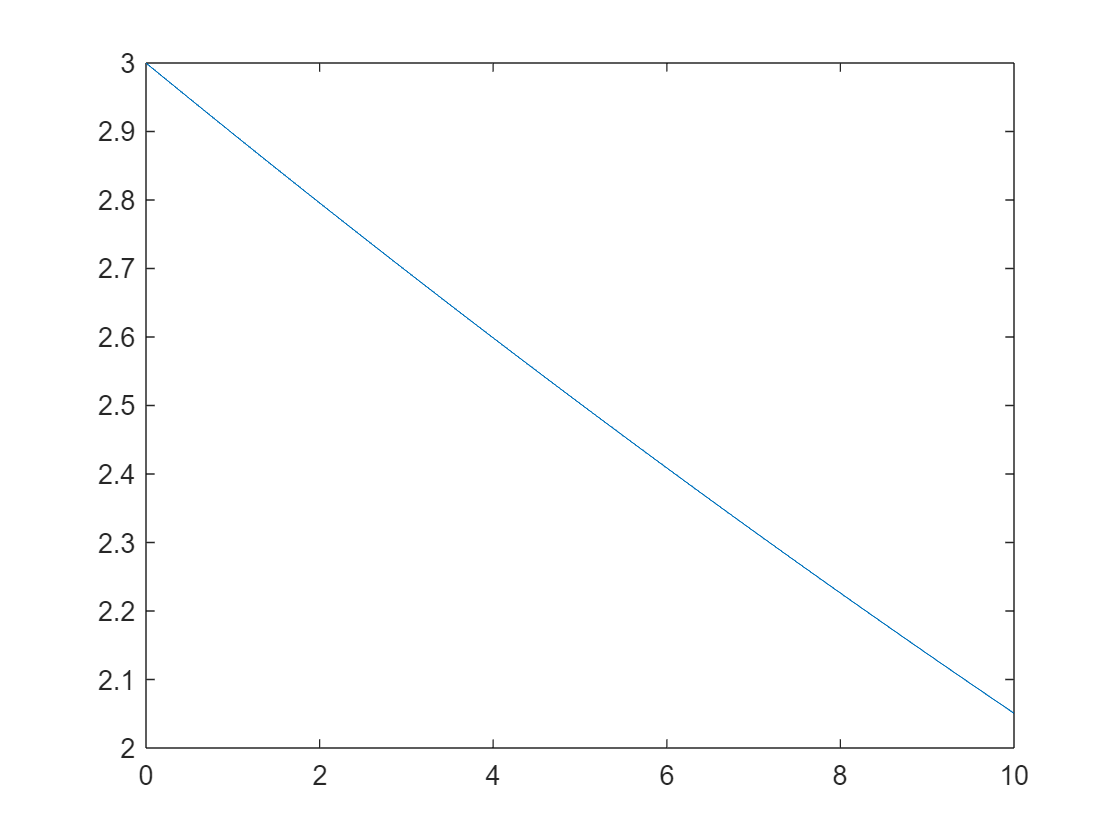

    2.0508



t = 0; y = 3;
while y > 0
    phi = f(t, y);
    y = y + phi*h;
    t = t + h;
end
disp(t)

opts = odeset('events', @gf);
[t, y, tfinal] = ode45(f, [0 Inf], y0, opts);
disp(tfinal)

#### Newton's Law of Cooling

According to Newton’s empirical law of cooling, the rate at which the temperature of a body changes is proportional to the difference between the temperature of the body and the temperature of the surrounding medium, the so-called ambient temperature. If T(t) represents the temperature of a body at time t, Tm the temperature of the surrounding medium, and dT/dt the rate at which the temperature of the body changes, then Newton’s law of cooling translates into the differential equation


$$\frac{\mathrm{d}}{\mathrm{d}t}T=k\left(T-T_m \right)$$


where k is a constant of proportionality.

Use the MATLAB function ode23 to approximate the temperature T at t = 4 min. of a ceramic insulator baked at $400\degree C$ and cooled in a room in which the temperature is $25\degree C$. Use k = −0.213.

#### Chemical Reaction 

The reaction between nitrous oxide and oxygen to form nitrogen dioxide is given by the balanced chemical equation $2\textrm{NO}+O_2 =2NO_2$. At high temperatures, the dependence of the rate of this reaction on the concentrations of $\textrm{NO}$, $O_2$, and $NO_2$ is complicated. However, at $25\degree C$ the rate at which $NO_2$ is formed obeys the law of mass action and is given by the differential equation


$$\frac{\mathrm{d}}{\mathrm{d}t}x=k{\left(\alpha -x\right)}^2 \left(\beta -\frac{x}{2}\right)$$


where x(t) denotes the concentration of $NO_2$ at time t, k is the rate constant, α is the initial concentration of $\textrm{NO}$, and β is the initial concentration of $O_2$.

Let α = 0.0010 mole/L, β = 0.0041 mole/L, k = 7.13 × 10^3 (L)^2/(mole)^2(sec.), and x(0) = 0 mole/L. Use the MATLAB function ode45 to approximate the concentration of $\textrm{NO}$ in the time interval [0, 10].

#### Modeling a fluid-mechanical system

A cylindrical water tank has cross-sectional area $A_1$ and water level $h_1 \left(t\right)$and is fed from the top by an input volumetric flow of water $f_1 \left(t\right)$. It has an orifice at height $h_2$ whose effective cross-sectional area is $A_2$, through which flows the output volumeris flow $f_2 \left(t\right)$. Graph the water level versus time for a tank that is initially empty and has a constant volumetric inflow ${f_1 =0\ldotp 004\;m}^3 /s$. Assume $A_1 =1m^2$ and $A_2 =0\ldotp 0005m^2$.

Under certain simplifying equations, the velocity of the water flowing out the orifice is given by Toriceli's equation $v_2 \left(t\right)=\sqrt{2g\left(h_1 \left(t\right)-h_2 \right)}$, where $g$ is the acceleration due to Earth's gravity. The rate of change of the volume $V\left(t\right)=A_1 h_1 \left(t\right)$ of water in the tank is the volumetric inflow minus the volumetric outflow rate


$$\frac{\mathrm{d}}{\mathrm{d}t}V=\frac{\mathrm{d}}{\mathrm{d}t}A_1 h_1 =f_1 -f_2 \left(t\right)$$



$$\frac{\mathrm{d}}{\mathrm{d}t}h_1 =\frac{{f_1 -A}_2 \sqrt{2g\left(h_1 \left(t\right)-h_2 \right)}}{A_1 }$$


As the water flows in, the water leavel increases and this increases the water outflow. The water level rises until de outflow equals the inflow and after that time the water level stays constant.

Para simular la dinámica de una poblacion se utiliza el modelo logistico:


$$p^{\prime } =k_{\textrm{gm}} \left(1-\frac{p}{p_{\max } }\right)p$$


donde *p *es la población, $k_{\textrm{gm}}$ es la tasa máxima de crecimiento en condiciones ilimitadas y$p_{\max }$es la capacidad de carga. Simula la población mundial entre 1950 y 2022, sabiendo que en 1950 había 2555 millones de personas. Para la simulación utiliza los siguientes valores de parametros: $k_{\textrm{gm}} =0\ldotp 026/\textrm{año}$ y $p_{\max } =12000$ millones de personas-

¿Cuántos millones de personas habrá en 2024?

In the study of dynamical systems, the phenomena of period doubling and chaos are observed. These phenomena can be seen when one uses a numerical scheme to approximate the solution to an initial-value problem for a nonlinear differential equation such as the following logistic model for population growth

$\frac{\mathrm{d}}{\mathrm{d}t}P=10P\left(1-P\right)$,    $P\left(0\right)=0\ldotp 1$

Use Euler’s method with h = 0.25 to approximate P(30). Note how the values of P jump from 1.22, 0.54, 1.16, and 0.70.

   57.7343



Circuit flowing through a resistor causes an increase in temperature, and this in turn increases its resistance R according to the formula $R=R_0 +b\;i$. When an E volt (V) battery is applied across such a resistor in a series with an L henry (h) inductor at time t = 0, the circuit current i = i(t) in milliamperes (ma) after t milliseconds (ms) satisfies the IVP

$L\frac{\mathrm{d}}{\mathrm{d}t}i=E-R_0 \;i-b\;i^2$ ,  $i\left(0\right)=0$

Suppose that L = 4 h, R0 = 1.2 kilohms, and b = 0.4 × 10^−7 kilohms/ma.

Approximate i(t) on the interval [0, 15] for E = 12 V.

A spherical tank has a circular orifice in its bottom through which the liquid flows out. 

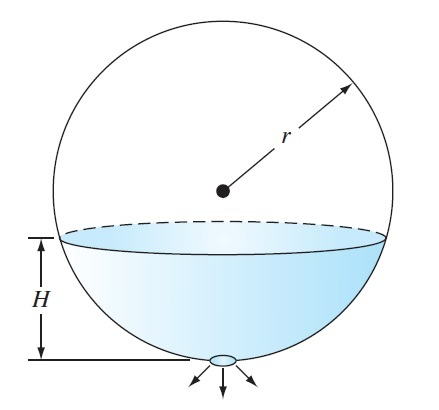

The flow rate through the hole can be estimated as $Q_{\textrm{out}} =\frac{d}{\mathrm{d}t}V=\;C\;A\;\sqrt{2\;g\;h}$ , where Qout = outflow (m3/s), V = volume of liquid in the  tank, C = an empirically derived coefficient, A = the area of the orifice (m2), g = the gravitational constant (= 9.81 m/s2), and h = the depth of liquid in the tank. Use a numerical method to determine how long it will take for the water to flow out of a 3-m diameter tank with an initial height of 2.75 m. Note that the orifice has a diameter of 3 cm and C = 0.55.

Sabemos que el volumen V está relacionado con la altura H


$$V=\frac{\pi H^2 \left(3r-H\right)}{3}$$


derivando esta ecuación tenemos


$$\frac{d}{\mathrm{d}t}V=\left(2\pi \textrm{rH}-\pi H^2 \right)\frac{\mathrm{d}}{\mathrm{d}t}H$$


Susbtituyendo en $Q_{\textrm{out}}$ obtenemos


$$\frac{\mathrm{d}}{\mathrm{d}t}H=-\frac{\textrm{CA}\sqrt{2\textrm{gH}}}{2\pi \textrm{rH}-\pi H^2 }$$


El área A del orificio es


$$A=\pi {\textrm{ro}}^2$$


In the investigation of a homicide or accidental death, it is often important to estimate the time of death. From the experimental observations, it is known that the surface temperature of an object changes at a rate proportional to the difference between the temperature of the object and that of the surrounding environment or ambient temperature. This is known as Newton’s law of cooling. Thus, if T(t) is the temperature of the object at time t, and Ta is the constant ambient temperature:


$$\frac{\mathrm{d}}{\mathrm{d}t}T=-K\left(T-T_a \right)$$


where K > 0 is a constant of proportionality. 

Suppose that at time t = 0 a corpse is discovered and its temperature is measured to be To. We assume that at the time of death, the body temperature Td was at the normal value of 37 °C.

Suppose that the temperature of the corpse when it was discovered was 29.5 °C, and that two hours later, it is 23.5 °C.

The ambient temperature is 20 °C.

(a) Determine K and the time of death.

(b) Solve the ODE numerically and plot the results.

  57.6309 + 0.0000i

